`Homework 1 (UQ4PDE)`

`Task 1`

N = 2; %Dimension of the functions considered
M = 1000;
n = 100; %time stepping schemes number of points
M_3 = 100000; % Number of samples used in third moment estimation for lambda
c0 = 1.65;
C_BE = 0.4748;

*1) Oscillator function*

What exactly is $c_0$ in the hints and how is Berry Esseen useful here?

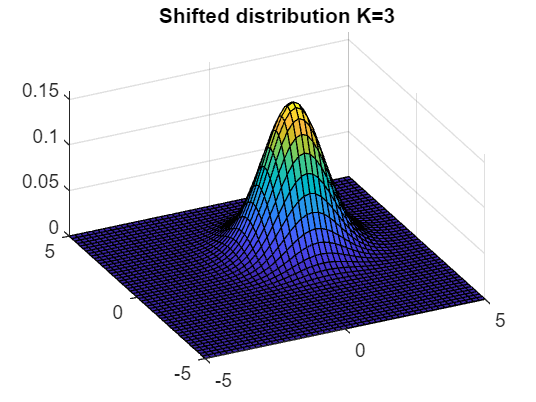

%{
I_ex_osc = exact_ref_solutions('Oscillator', N);

estimates = zeros([1 M]);
variances = zeros([1 M]);
exact_err = zeros([1 M]);
stat_err = zeros([1 M]);
BE_err_bound = zeros([1 M]);

for k=1:M
    rng(7)
    [estimates(k), variances(k)] = Monte_Carlo_HW1(@f_Oscillatory, N, k);
    exact_err(k) = abs(estimates(k) - I_ex_osc);
end

samples_3rd = rand(N, M_3);   % Generate samples
Y = f_Oscillatory(samples_3rd); % Apply function on samples to get samples Y_i
MC_est_3rd_moment = 1/M_3*sum(abs(Y - estimates(end)).^3); % MC estimate for 3rd moment

lambda = MC_est_3rd_moment^(1/3)/variances(end)

for k=1:M
    BE_err_bound(k) = 2*normcdf(c0) - 1 - 2*C_BE*lambda^3/((1+c0)^3*sqrt(k));
    stat_err(k) = c0*variances(end)/sqrt(k);
end

% Log Log plot for statistical error vs exact error
loglog(1:M, exact_err, 1:M, BE_err_bound, 1:M, stat_err)
legend('Exact error', 'Berry Esseen prob.', 'BE bound', fontsize=7, location='southwest')
title("Oscillator function")
%}

% Define the parameters of the Gaussian distribution
mu = [1.12245, 1.12245];  % mean
sigma = [1, 0; 0, 1];  % covariance matrix

% Define the grid of x- and y-values
x = linspace(-5, 5, 50);
y = linspace(-5, 5, 50);
[X, Y] = meshgrid(x, y);

% Evaluate the Gaussian function at each point in the grid
Z = zeros(size(X));
for i = 1:numel(X)
    Z(i) = mvnpdf([X(i), Y(i)], mu, sigma);
end

% Create a surface plot of the Gaussian function
figure;
surf(X, Y, Z);
%xlabel('x');
%ylabel('y');
%zlabel('f(x, y)');
title('Shifted distribution K=3');